# GQ 2 Modèle DCC et Granger Test

clc;
clear,
data = readtable('inefficiency.xlsx');

dates = data(:,1); % date
data = data(:,2:end); % inefficiency
varNames = data.Properties.VariableNames;

### Test d'augmented Dickey Fuller

adfLags = 9;
[adfStats, adfP] = performADFTest(data, adfLags);

adfResults = table( ...
    varNames(:), ...
    adfStats(:), ...
    adfP(:), ...
    repmat(adfLags, length(varNames), 1), ...
    'VariableNames', {'MarketIndex', 'Statistic', 'pValue', 'Lags'} ...
)

adfResults = 4×4 table
    MarketIndex    Statistic     pValue      Lags
    ___________    _________    _________    ____

    {'s_p500' }     -1.5493       0.11446     9  
    {'ssec'   }     -3.1599     0.0021295     9  
    {'ftse100'}     -1.9659      0.047301     9  
    {'ftsemib'}     -1.8966      0.055321     9  


data_diff = diff(data);
adfLags = 9;
[adfStats, adfP] = performADFTest(data_diff, adfLags);


adfResults = table( ...
    varNames(:), ...
    adfStats(:), ...
    adfP(:), ...
    repmat(adfLags, length(varNames), 1), ...
    'VariableNames', {'MarketIndex', 'Statistic', 'pValue', 'Lags'} ...
)

adfResults = 4×4 table
    MarketIndex    Statistic    pValue    Lags
    ___________    _________    ______    ____

    {'s_p500' }      -6.749     0.001      9  
    {'ssec'   }     -8.0846     0.001      9  
    {'ftse100'}     -7.4103     0.001      9  
    {'ftsemib'}     -7.1484     0.001      9  


## Test de présence d'effet ARCH

archLags = 12;
[archStats, archP] = performARCHTest(data_diff, archLags);

archResults = table( ...
    varNames(:), ...
    archStats(:), ...
    archP(:), ...
    repmat(archLags, length(varNames), 1), ...
    'VariableNames', {'MarketIndex', 'Statistic', 'pValue', 'Lags'} ...
)

archResults = 4×4 table
    MarketIndex    Statistic      pValue      Lags
    ___________    _________    __________    ____

    {'s_p500' }     125.64               0     12 
    {'ssec'   }     80.735      2.9881e-12     12 
    {'ftse100'}     117.81               0     12 
    {'ftsemib'}     48.817      2.2512e-06     12 


## GARCH

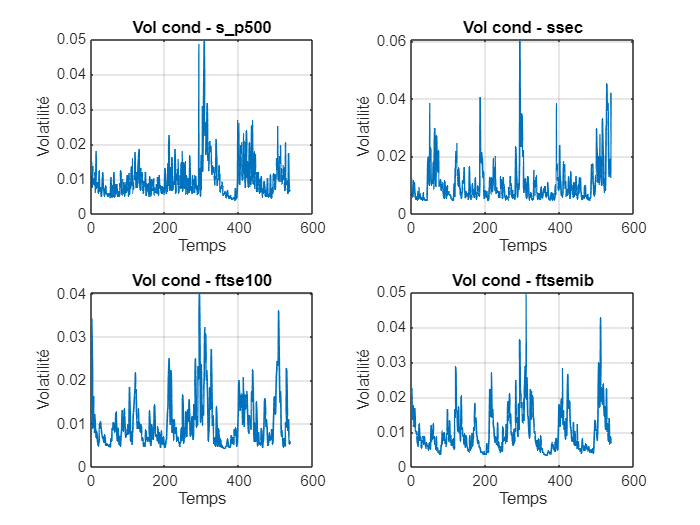

% Supposons que "I_matrix" soit une table ou une matrice de séries
[condVols, residuals, aics, pqs] = estimateGARCH(data_diff, 10, 10);


% ========================
% Plot des volatilities conditionnelles
% ========================
figure('Name', 'Volatilités Conditionnelles');
tiledlayout('flow');

[T, N] = size(condVols);
for i = 1:N
    nexttile;
    plot(condVols(:, i), 'LineWidth', 1);
    title(['Vol cond - ', varNames{i}], 'Interpreter', 'none');
    xlabel('Temps');
    ylabel('Volatilité');
    grid on;
end

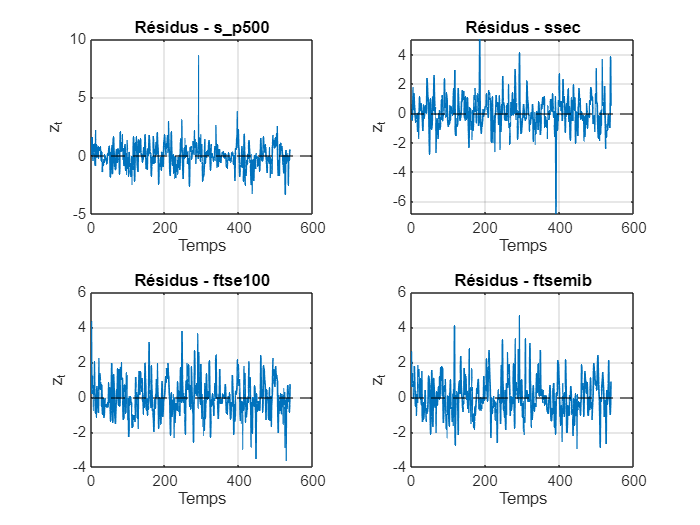

figure('Name', 'Résidus Standardisés');
tiledlayout('flow');

for i = 1:N
    nexttile;
    plot(residuals(:, i), 'LineWidth', 1);
    title(['Résidus - ', varNames{i}], 'Interpreter', 'none');
    xlabel('Temps');
    ylabel('z_t');
    yline(0, '--k');
    grid on;
end

## ARCH on resids

residuals = array2table(residuals, 'VariableNames',varNames);
condVols = array2table(condVols, 'VariableNames',varNames);
[archStats, archP] = performARCHTest(residuals , archLags);

archResults = table( ...
    varNames(:), ...
    archStats(:), ...
    archP(:), ...
    repmat(archLags, length(varNames), 1), ...
    'VariableNames', {'MarketIndex', 'Statistic', 'pValue', 'Lags'} ...
)

archResults = 4×4 table
    MarketIndex    Statistic    pValue     Lags
    ___________    _________    _______    ____

    {'s_p500' }     4.6646      0.96825     12 
    {'ssec'   }      3.837       0.9862     12 
    {'ftse100'}     6.8499      0.86737     12 
    {'ftsemib'}     9.3236      0.67507     12 



____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.544245e+03    0.000e+00    7.352e-01
    1       7    1.544431e+03    0.000e+00    8.301e+01    8.947e-03
    2      10    1.544292e+03    0.000e+00    1.432e+01    1.797e-02
    3    

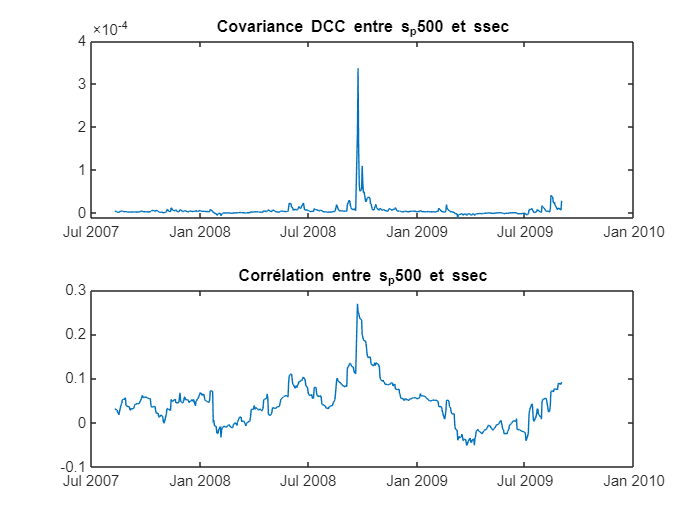


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.433866e+03    0.000e+00    3.402e+00
    1      14    1.433862e+03    0.000e+00    6.673e+00    3.149e-03
    2      17    1.433853e+03    0.000e+00    1.397e+01    1.684e-02
    3    

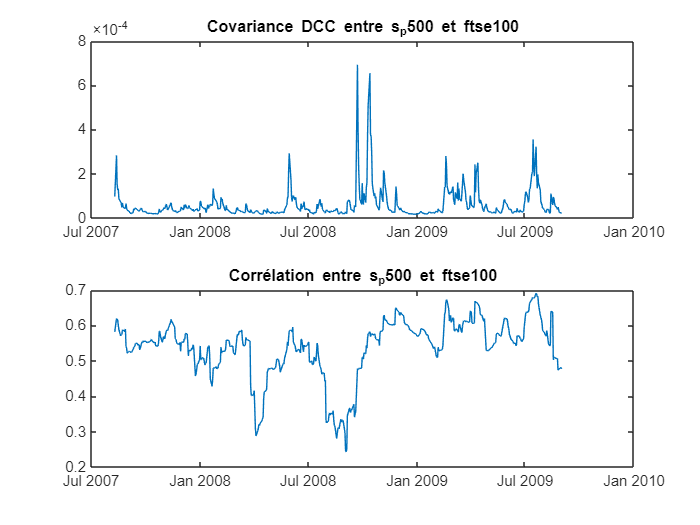


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.462765e+03    0.000e+00    1.013e+02
    1       7    1.461936e+03    0.000e+00    6.347e+01    4.230e-01
    2      10    1.461510e+03    0.000e+00    1.399e+01    6.030e-02
    3    

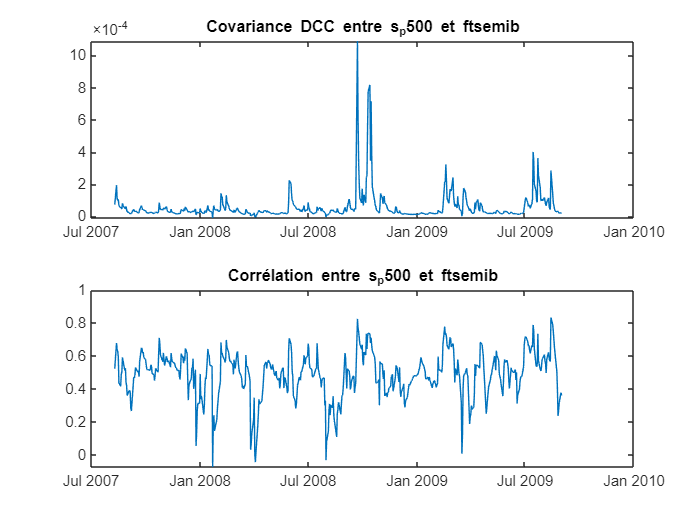


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.546629e+03    0.000e+00    1.465e+01
    1       6    1.542343e+03    0.000e+00    5.045e+01    6.645e-01
    2       9    1.539949e+03    0.000e+00    2.173e+01    2.644e-01
    3    

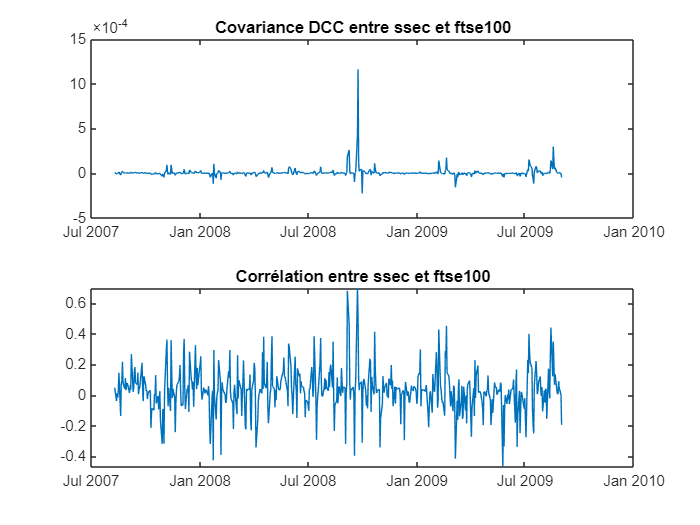


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.559560e+03    0.000e+00    3.614e+01
    1       6    1.558812e+03    0.000e+00    1.575e+02    9.156e-01
    2       9    1.555051e+03    0.000e+00    6.940e+01    1.540e-01
    3    

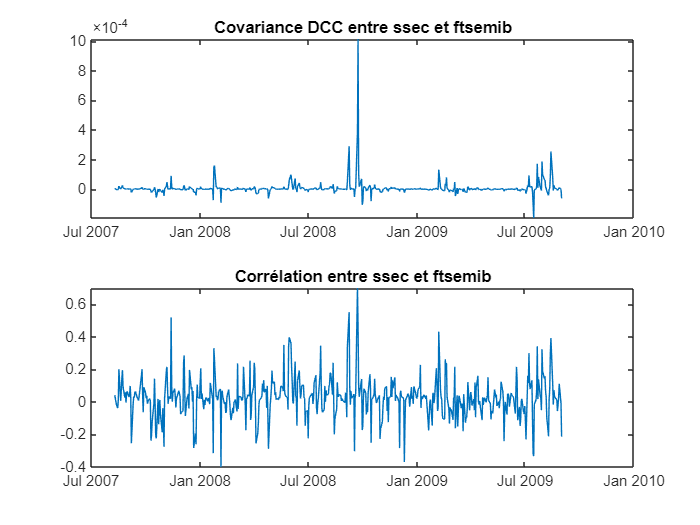


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.375005e+03    0.000e+00    2.133e+02
    1       6    1.364180e+03    0.000e+00    2.314e+02    8.458e-01
    2       9    1.362404e+03    0.000e+00    1.399e+02    1.288e-02
    3    

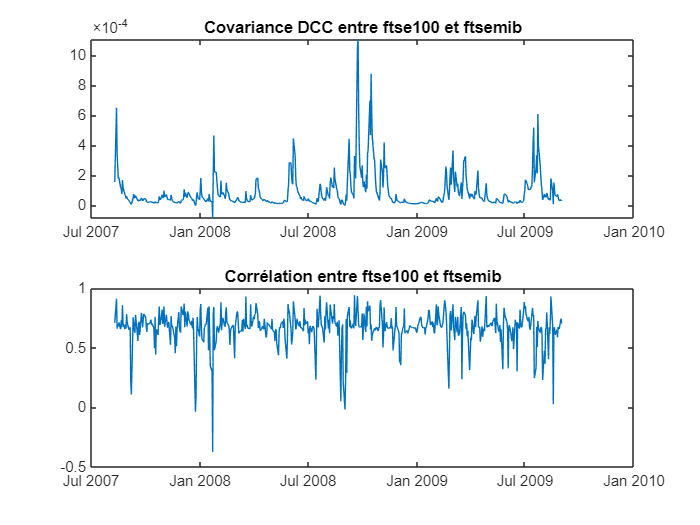

data1 is a table, converting to array.
data2 is a table, converting to array.


table = 2×4 table
         Estimate          StdError          tValue          pValue
    ___________________    _________    _________________    ______

    0.64225    -0.19886    0.0090784    70.744    -21.904    0    0
    0.10206     0.48549    0.0092504    11.033     52.483    0    0


% Paramètres du modèle DCC
M = 1;
L = 0;
N = 1;
P = 1;
O = 0; % Mettre à 1 si présence d'un effet d'asymétrie
Q = 1;
data_dcc = data_diff;
numCols = size(data_dcc, 2);
for i = 1:numCols
    for j = i+1:numCols
        % Extract the pair of columns as vectors
        data1 = table2array(data_dcc(:, i));
        data2 = table2array(data_dcc(:, j));
        
        colName1 = data.Properties.VariableNames{i};
        colName2 = data.Properties.VariableNames{j};

        % Compute DCC
        [cov_dcc, corr_dcc] = computeDCC(data1, data2, M, L, N, P, O, Q);

        % Create a new figure for each pair
        figure;

        % Plot the results
        subplot(2, 1, 1);
        plot(table2array(dates(2:end,:)), cov_dcc);
        title(['Covariance DCC entre ', colName1, ' et ', colName2]);

        subplot(2, 1, 2);
        plot(table2array(dates(2:end,:)), corr_dcc);
        title(['Corrélation entre ', colName1, ' et ', colName2]);
    end
end

## Granger Causality Test + VAR

[result_VAR, result_Granger] = estimate_VAR(data_diff(:,3), data_diff(:,4), P)

data1 is a table, converting to array.
data2 is a table, converting to array.


result_VAR = 2×4 table
         Estimate          StdError          tValue          pValue
    ___________________    _________    _________________    ______

    0.64225    -0.19886    0.0090784    70.744    -21.904    0    0
    0.10206     0.48549    0.0092504    11.033     52.483    0    0


result_Granger = 2×4 table
         Test         WaldStat      pValue      Decision
    ______________    ________    __________    ________

    "Y1 causes Y2"     18.118     2.0762e-05    "Cause" 
    "Y2 causes Y1"     104.02              0    "Cause" 
